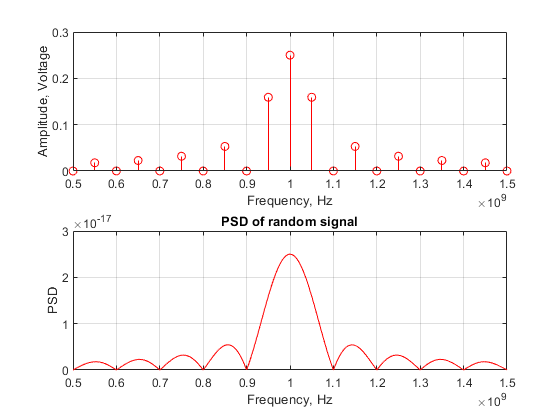

% BASK

tau = 10e-9; % Symbol duration, ns
f0 = 1.0e+9; % Carrier frequency, GHz
U = 1; % Amplitude of carrier signal
w0 = 2*pi*f0; % Angular frequency of carrier
w = pi/tau; % Base harmonic angular frequency
k0 =  w0/w; % Carrier frequency index

% Define the frequency index range
k = k0 + (-10:10);

% Spectrum of periodic signal
phi = (k*w - w0)*tau/2; % Argument of sinc function
C_BASK = sinc(phi/pi)*U/4*1i; % Fourier series coefficients

% plot results
subplot(2, 1, 1);
stem(k*w/(2*pi), abs(C_BASK), 'r')
grid on;
xlabel('Frequency, Hz');
ylabel('Amplitude, Voltage');


% Spectrum of SPD
W = (k(1):0.01:k(end))*w; % Angular frequency
phi2 = (W - w0)*tau/2; % Argument of sinc function
S_BASK = 2*tau*sinc(phi2/pi)*U/4*1i; % Spectral function
G_BASK = (1/2)*tau*abs(S_BASK);

% plot results
subplot(2, 1, 2);
plot(W/(2*pi), abs(G_BASK), 'r')
grid on;
xlabel('Frequency, Hz');
ylabel('PSD');
title('PSD of random signal');